# Plos One

## Bicluster Samples

A1 = ones(4,6)*rand();
A2 = [rand()*ones(4,1),rand()*ones(4,1),rand()*ones(4,1),rand()*ones(4,1),rand()*ones(4,1),rand()*ones(4,1)];
% a=[rand();rand();rand();rand()];
% A3 = [rand()*ones(4,1)+a,rand()*ones(4,1)+a,a,rand()*ones(4,1),rand()*ones(4,1)+a,rand()*ones(4,1)+a];

a = [];
for i = 1:60
    a=[a;rand()];
end
A3 = a;
for i = 1:79
    A3=[A3,a+rand()*ones(60,1)];
end



b = [];
for i = 1:60
    b=[b;rand()];
end
A4 = [];
for i = 1:80
    A4=[A4,b*rand()];
end

A=rand(3,3); A=A*A'+A'*A; [U,S,V]=svd(A); [E,e]=eig(A); % A*E-E*e [d,ind]=sort(diag(e),'descend'); e=e(ind,ind); E=E(:,ind); A*E-E*e

## Prove on a line is wrong

[U,S,V]=svd(A4);
U(:,1:2)*S(1:2,1:2)*(V(:,1:2))'-A4

ans = 1.0e-14 *

    0.0777   -0.0056         0   -0.0278    0.0056    0.0222   -0.0111    0.0222   -0.0389    0.0014   -0.0056   -0.0056    0.0056    0.0007   -0.0056    0.0111   -0.0002   -0.0111    0.0021   -0.0056   -0.0111         0         0   -0.0014   -0.0111   -0.0167         0         0   -0.0014   -0.0002   -0.0056   -0.0111    0.0056    0.0111   -0.0111         0         0   -0.0014   -0.0056   -0.0014   -0.0056         0         0   -0.0222    0.0222         0   -0.0056         0         0   -0.0167
    0.0444   -0.1166    0.0111   -0.0999    0.0278    0.2109   -0.0777   -0.0111   -0.1443    0.0069   -0.0722         0    0.0111   -0.0083   -0.0222   -0.1221   -0.0010   -0.0444         0         0   -0.0278   -0.0083    0.0666   -0.0083   -0.0222    0.0111    0.0069   -0.0028   -0.0083   -0.0014   -0.0278    0.1332   -0.0111   -0.0056    0.0444   -0.0014   -0.0555   -0.0069    0.0056   -0.0333   -0.0555    0.0003   -0.2554   -0.0555    0.0222   -0.0333   -0.0278   -0.0167  

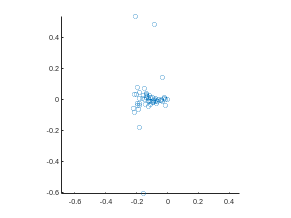

x = U(:,1);
y = U(:,2);
figure
scatter(x,y)
daspect([1 1 1])
pbaspect([1 1 1])

## Pro 3

B = [A3;A4];
[U,S,V]=svd(B);
S

S =    78.3466         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   12.9032         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     